# Sample 13-4

## 辞書学習

畳込み辞書学習

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Dictionary learning

Convolutional dictionary learning

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


### パラメータ設定

(Parameter settings)

- ツリーレベル (Tree levels)

- 間引き率 (Decimation factor)

- チャンネル数 (Number of channels)

- スパース率 (Sparsity ratio)

- 繰返し回数 (Number of iterations)

% Tree levels
nLevels = 3;

% Decimation factor (Strides)
decFactors = [2 2];
nDecs = prod(decFactors);

% Number of channels
nChannels = [3 3];
redundancyRatio = sum(nChannels)/nDecs

redundancyRatio = 1.5000


% Sparsity ratio
sparsityRatio = 0.1;

% Number of iterations
nIters = 30;

## 画像の読込

(Read image)

- 
$$\mathbf{u}\in\mathbb{R}^{N}$$


% Read image
u = imresize(im2single(imread('cameraman.tif')),[64 64]);% rgb2gray(im2single(imread('./data/lena.png')));
nDims = numel(u);

### 畳込み辞書学習

 (Convolutional dictionary learning)

#### 問題設定 (Problem setting):

    
$$\{\hat{\mathbf{\theta}},\{ \hat{\mathbf{s}}_n \}\}=\arg\min_{\{\mathbf{\theta},\{\mathbf{s}_n\}\}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{v}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{s}}_n\|_2^2,\ \quad\mathrm{s.t.}\ \forall n, \|\mathbf{s}_n\|_0\leq K,$$$


ただし， $\mathbf{D}_{\mathbf{\theta}}$ は $\mathbf{\theta}}$を設計パラメータとする畳込み辞書とする．(where $\mathbf{D}_{\mathbf{\theta}}$ is a convolutional dictionary with the design parameter vector $\mathbf{\theta}}$.)

#### アルゴリズム (Algorithm):

スパース近似ステップと辞書更新ステップを繰返す．

- スパース近似ステップ (Sparse approximation step)

                
$$\hat{\mathbf{s}}_n=\arg\min_{\mathbf{s}_n}\frac{1}{2} \|\mathbf{v}_n-\hat{\mathbf{D}}\mathbf{s}_n\|_2^2\ \quad \mathrm{s.t.}\ \|\mathbf{s}_n\|_0\leq K$$


- 辞書更新ステップ (Dictionary update step)

                
$$\hat{\mathbf{\theta}}=\arg\min_{\mathbf{\theta}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{v}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{s}}_n\|_2^2$$


                
$$\hat{\mathbf{D}}=\mathbf{D}_{\hat{\mathbf{\theta}}$$


係数の数 (Number of coefficients)

nCoefs = floor(sparsityRatio*nDims);

### 二変量ラティス構造冗長フィルタバンク

(Bivariate lattice-structure oversampled filter banks )

例としてチャンネル数 $P$ （偶数）, ポリフェーズ次数 $(N_\mathrm{v},N_\mathrm{h})$ （偶数）のタイプI の非分離冗長重複変換(NSOLT)

        
$$\mathbf{E}(z_\mathrm{v},z_\mathbf{h})
=
\left(\prod_{k_\mathrm{h}=1}^{N_\mathrm{h}/2}
{\mathbf{V}_{2k_\mathrm{h}}^{\{\mathrm{h}\}}}\bar{\mathbf{Q}}(z_\mathrm{h}){\mathbf{V}_{2k_\mathrm{h}-1}^{\{\mathrm{h}\}}}{\mathbf{Q}}(z_\mathrm{h})\right)
%
\left(\prod_{k_{\mathrm{v}}=1}^{N_\mathrm{v}/2}{\mathbf{V}_{2k_\mathrm{v}}^{\{\mathrm{v}\}}}\bar{\mathbf{Q}}(z_\mathrm{v}){\mathbf{V}_{2k_\mathrm{v}-1}^{\{\mathrm{v}\}}}{\mathbf{Q}}(z_\mathrm{v})\right)
%
\mathbf{V}_0\mathbf{E}_0$$


        
$$\mathbf{R}(z_\mathrm{v},z_\mathbf{h})
=\mathbf{E}^T(z_\mathrm{v}^{-1},z_\mathrm{h}^{-1})$$


を採用する．ここで，

- $\mathbf{E}(z_\mathrm{v},z_\mathrm{h})$:  分析フィルタバンクの$P\times M$タイプⅠポリフェーズ行列

- $\mathbf{R}(z_\mathrm{v},z_\mathrm{h})$: 合成フィルタバンクの $M\times P$タイプⅡポリフェーズ行列

- $z_d\in\mathbb{C}, d\in\{\mathrm{v},\mathrm{h}\}$: Z-変換の方向 $d$の変数

- $N_d\in \mathbb{N}, d\in\{\mathrm{v},\mathrm{h}\}$: 方向 $d$ のポリフェーズ次数（重複ブロック数）

- $\mathbf{V}_0=\left(\begin{array}{cc}\mathbf{W}_{0} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_0\end{array}\right)
%
\left(\begin{array}{c}\mathbf{I}_{M/2} \\ 
\mathbf{O} \\
\mathbf{I}_{M/2} \\
\mathbf{O}
\end{array}\right)\in\mathbb{R}^{P\times M}$,$\mathbf{V}_n^{\{d\}}=\left(\begin{array}{cc}\mathbf{I}_{P/2} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_n^{\{d\}}\end{array}\right)\in\mathbb{R}^{P\times P}, d\in\{\mathrm{v},\mathrm{h}\}$, ただし， $\mathbf{W}_0, \mathbf{U}_0,\mathbf{U}_n^{\{d\}}\in\mathbb{R}^{P/2\times P/2}$は直交行列．

- $\mathbf{Q}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  z^{-1}\mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\bar{\mathbf{Q}}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} z\mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  \mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\mathbf{B}_{P}=\frac{1}{\sqrt{2}}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{I}_{P/2} \\ \mathbf{I}_{P/2} &  -\mathbf{I}_{P/2}\end{array}\right)$

【Example】For $P/2=3$, a parametric orthonormal matrix $\mathbf{U}(\mathbf{\theta},\mathbf{\mu})$ can be constructed by 

        
$$\mathbf{U}(\mathbf{\theta},\mathbf{\mu}) \colon = \left(\begin{array}{cc} \mu_0 & 0& 0\\ 0 & \mu_1 & 0 \\ 0 & 0 & \mu_2 \end{array}\right)
%
\left(\begin{array}{cc} 
 0 & 0 & 0 \\
0 & \cos\theta_2& -\sin\theta_2 \\ 
0 & \sin\theta_2 & \cos\theta_2 
\end{array}\right)
%
\left(\begin{array}{cc} 
\cos\theta_1& 0 & -\sin\theta_1  \\ 
 0 & 0 & 0 \\
\sin\theta_1 & 0 &  \cos\theta_1 
 \end{array}\right)
%
\left(\begin{array}{cc} 
\cos\theta_0& -\sin\theta_0 & 0 \\ 
\sin\theta_0 & \cos\theta_0 & 0 \\
 0 & 0 & 0 \end{array}\right),$$


        
$${\mathbf{U}(\mathbf{\theta},\mathbf{\mu})}^T = 
%
\left(\begin{array}{cc} 
\cos\theta_0& \sin\theta_0 & 0 \\ 
-\sin\theta_0 & \cos\theta_0 & 0 \\
 0 & 0 & 0 \end{array}\right)
%
\left(\begin{array}{cc} 
\cos\theta_1& 0 & \sin\theta_1  \\ 
 0 & 0 & 0 \\
-\sin\theta_1 & 0 &  \cos\theta_1 
 \end{array}\right)
%
\left(\begin{array}{cc} 
 0 & 0 & 0 \\
0 & \cos\theta_2& \sin\theta_2 \\ 
0 & -\sin\theta_2 & \cos\theta_2 
\end{array}\right)
%
\left(\begin{array}{cc} \mu_0 & 0& 0\\ 0 & \mu_1 & 0 \\ 0 & 0 & \mu_2 \end{array}\right),$$


where $\mathbf{\theta}\in\mathbb{R}^{(P-2)P/8}$ and $\mathbf{\mu}=\{-1,1\}^{P/2}$. For the sake of simplification, the sign parameters $\mu_k$ are fixed to $-1$for $\mathbf{U}_n^{\{d\}}$ witn odd $n$, otherwise they are fixed to $+1$.

#### カスタムレイヤとネットワークの定義

合成NSOLT (Synthesis NSOLT)の実装にDeep Learning Toolbox のカスタムレイヤを利用．

学習レイヤの定義 (w/ Learnable properties)

- Final rotation: $\mathbf{V}_0^T$ (msip.nsoltFinalRotationLayer)

- Intermediate rotation: ${\mathbf{V}_n^{\{d\}}}^T$ (msip.nsoltIntermediateRotationLayer)

非学習レイヤの定義 (w/o Learnable properties)

- Bivariate inverese DCT (2-D IDCT): $\mathbf{E}_0^T=\mathbf{E}_0^{-1}$ (msip.nsoltBlockDctLayer)

- Vertical up concatenation: $\mathbf{Q}^T(z_\mathrm{v}^{-1})$ (msip.nsoltAtomExtensionLayer)

- Vertical down concatenation: $\bar{\mathbf{Q}}^T(z_\mathrm{v}^{-1})$  (msip.nsoltAtomExtensionLayer)

- Horizontal left concatenation: $\mathbf{Q}^T(z_\mathrm{h}^{-1})$ (msip.nsoltAtomExtensionLayer)

- Horizontal right concatenation: $\bar{\mathbf{Q}}^T(z_\mathrm{h}^{-1})$ (msip.nsoltAtomExtensionLayer)

【References】 

- S. Muramatsu, T. Kobayashi, M. Hiki and H. Kikuchi, "Boundary Operation of 2-D Nonseparable Linear-Phase Paraunitary Filter Banks," in IEEE Transactions on Image Processing, vol. 21, no. 4, pp. 2314-2318, April 2012, doi: 10.1109/TIP.2011.2181527.

- S. Muramatsu, K. Furuya and N. Yuki, "Multidimensional Nonseparable Oversampled Lapped Transforms: Theory and Design," in IEEE Transactions on Signal Processing, vol. 65, no. 5, pp. 1251-1264, 1 March1, 2017, doi: 10.1109/TSP.2016.2633240.

- Furuya, K., Hara, S., Seino, K., & Muramatsu, S. (2016). Boundary operation of 2D non-separable oversampled lapped transforms. *APSIPA Transactions on Signal and Information Processing, 5*, E9. doi:10.1017/ATSIP.2016.3.

profile on
import msip.*
analysisNsoltLayers = [
    imageInputLayer(size(u),'Normalization','none')
    nsoltBlockDct2Layer(decFactors,'E0')
    nsoltInitialRotationLayer(nChannels,decFactors,'V0')
    nsoltAtomExtensionLayer(nChannels,'Qhrl','Right','Lower')
    nsoltIntermediateRotationLayer(nChannels,'Vh1','Analysis')
    nsoltAtomExtensionLayer(nChannels,'Qhlu','Left','Upper')
    nsoltIntermediateRotationLayer(nChannels,'Vh2','Analysis')
    nsoltAtomExtensionLayer(nChannels,'Qvdl','Down','Lower')
    nsoltIntermediateRotationLayer(nChannels,'Vv1','Analysis')
    nsoltAtomExtensionLayer(nChannels,'Qvuu','Up','Upper')
    nsoltIntermediateRotationLayer(nChannels,'Vv2','Analysis')
    ]

analysisNsoltLayers =   次の層をもつ 11x1 の Layer 配列:

     1   ''       イメージの入力                           64x64x1 イメージ
     2   'E0'     msip.nsoltBlockDct2Layer              Block DCT of size 2x2
     3   'V0'     msip.nsoltInitialRotationLayer        NSOLT initial rotation ( (ps,pa) = (3,3), (mv,mh) = (2,2) )
     4   'Qhrl'   msip.nsoltAtomExtensionLayer          Right shift Lower Coefs. (ps,pa) = (3,3)
     5   'Vh1'    msip.nsoltIntermediateRotationLayer   Analysis NSOLT intermediate rotation (ps,pa) = (3,3)
     6   'Qhlu'   msip.nsoltAtomExtensionLayer          Left shift Upper Coefs. (ps,pa) = (3,3)
     7   'Vh2'    msip.nsoltIntermediateRotationLayer   Analysis NSOLT intermediate rotation (ps,pa) = (3,3)
     8   'Qvdl'   msip.nsoltAtomExtensionLayer          Down shift Lower Coefs. (ps,pa) = (3,3)
     9   'Vv1'    msip.nsoltIntermediateRotationLayer   Analysis NSOLT intermediate rotation (ps,pa) = (3,3)


synthesisNsoltLayers = [
    nsoltIntermediateRotationLayer(nChannels,'Vv2~','Synthesis')
    nsoltAtomExtensionLayer(nChannels,'Qvuu~','Down','Upper')
    nsoltIntermediateRotationLayer(nChannels,'Vv1~','Synthesis')
    nsoltAtomExtensionLayer(nChannels,'Qvdl~','Up','Lower')
    nsoltIntermediateRotationLayer(nChannels,'Vh2~','Synthesis')
    nsoltAtomExtensionLayer(nChannels,'Qhlu~','Right','Upper')
    nsoltIntermediateRotationLayer(nChannels,'Vh1~','Synthesis')
    nsoltAtomExtensionLayer(nChannels,'Qhrl~','Left','Lower') 
    nsoltFinalRotationLayer(nChannels,decFactors,'V0~')
    nsoltBlockIdct2Layer(decFactors,'E0~') 
    regressionLayer()
    ]

synthesisNsoltLayers =   次の層をもつ 11x1 の Layer 配列:

     1   'Vv2~'    msip.nsoltIntermediateRotationLayer   Synthesis NSOLT intermediate rotation (ps,pa) = (3,3)
     2   'Qvuu~'   msip.nsoltAtomExtensionLayer          Down shift Upper Coefs. (ps,pa) = (3,3)
     3   'Vv1~'    msip.nsoltIntermediateRotationLayer   Synthesis NSOLT intermediate rotation (ps,pa) = (3,3)
     4   'Qvdl~'   msip.nsoltAtomExtensionLayer          Up shift Lower Coefs. (ps,pa) = (3,3)
     5   'Vh2~'    msip.nsoltIntermediateRotationLayer   Synthesis NSOLT intermediate rotation (ps,pa) = (3,3)
     6   'Qhlu~'   msip.nsoltAtomExtensionLayer          Right shift Upper Coefs. (ps,pa) = (3,3)
     7   'Vh1~'    msip.nsoltIntermediateRotationLayer   Synthesis NSOLT intermediate rotation (ps,pa) = (3,3)
     8   'Qhrl~'   msip.nsoltAtomExtensionLayer          Left shift Lower Coefs. (ps,pa) = (3,3)
     9   'V0~'     msip.nsoltFinalRotation

net = SeriesNetwork([analysisNsoltLayers synthesisNsoltLayers])

net =   SeriesNetwork のプロパティ:

         Layers: [22×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


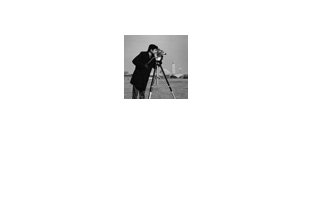

v = net.predict(u);
profile off
profile viewer

imshow(v)

psnr(u,v)

ans = single
143.7968

### 画像表示

(Image show)

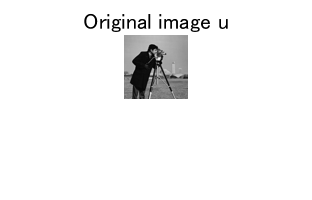

figure(1)
imshow(u);
title('Original image u')

figure(2)
%montage(imresize(atomicImages,8,'nearest')+.5,'BorderSize',[2 2],'Size',[ceil(nChannels/8) 8])
%title('Atomic images of initial dictionary (DCT & random)')

#### スパース近似ステップと辞書更新ステップの繰り返し

- スパース近似： 直交マッチング追跡 (OMP)

- 辞書更新： 特異値分解と1-ランク近似 (SVD and 1-rank approximation)

交互ステップの繰返し計算 (Iterative calculation of alternative steps)

%cost = zeros(1,nIters);
for iIter = 1:nIters

    % Sparse approximation

    % Dictionary update

    %cost(iIter) = ...
end

コスト評価のグラフ (Graph of cost variation)

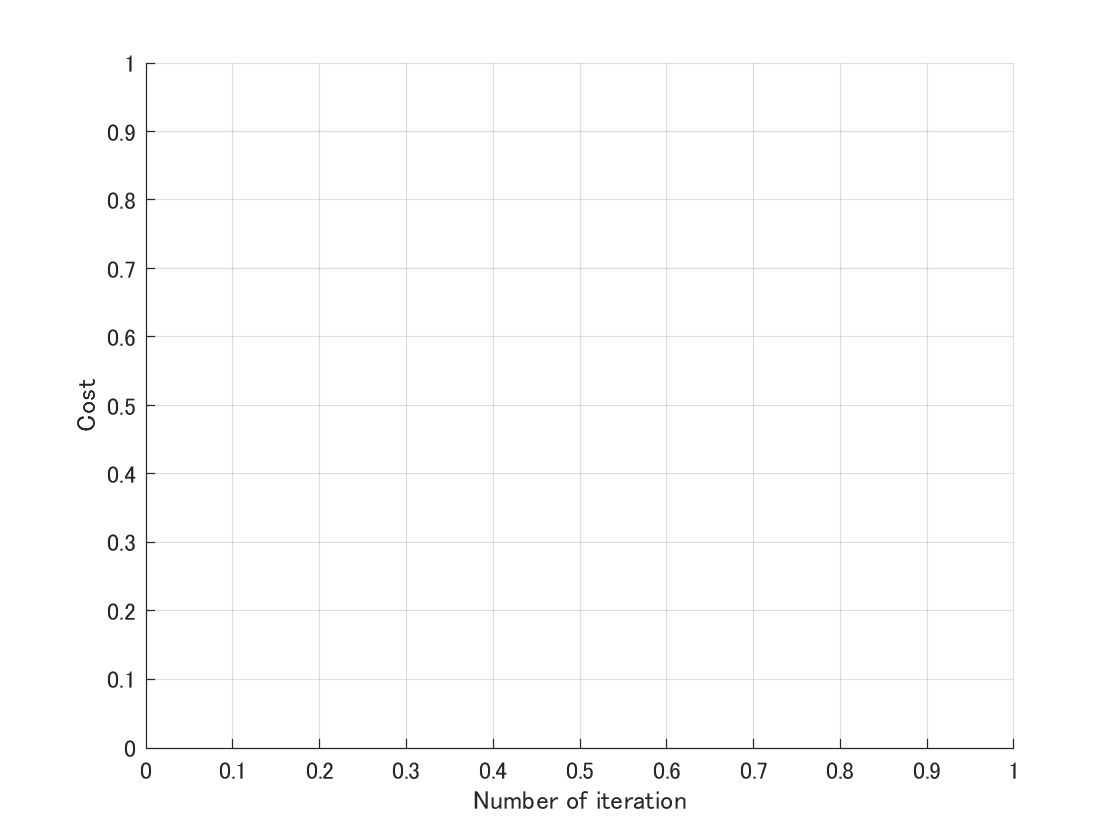

figure(3)
%plot(cost)
xlabel('Number of iteration')
ylabel('Cost')
grid on

要素ベクトルを要素画像に変換 (Reshape the atoms into atomic images)

%{
atomicImages = zeros(stride(1),stride(2),nChannels);
for iAtom = 1:nChannels
    atomicImages(:,:,iAtom) = reshape(Phi(:,iAtom),stride(1),stride(2));
end
figure(4)
montage(imresize(atomicImages,8,'nearest')+.5,'BorderSize',[2 2],'Size',[ceil(nChannels/8) 8])
title('Atomic images of K-SVD')
%}

### 繰返しハード閾値処理 

(Function of iterative hard thresholding)

% T. Blumensath and M. E. Davies, "Normalized Iterative Hard Thresholding: Guaranteed Stability and Performance," in IEEE Journal of Selected Topics in Signal Processing, vol. 4, no. 2, pp. 298-309, April 2010, doi: 10.1109/JSTSP.2010.2042411.

© Copyright, Shogo MURAMATSU, All rights reserved.